# Risposte per i test Cap 7

I = integral(f,a,b) → built in in matlab

## Capitoli del libro

### Formule di quadratura del punto medio

### Formule di quadratura del trapezio

#### Stima di M (Numero di sottointervalli)

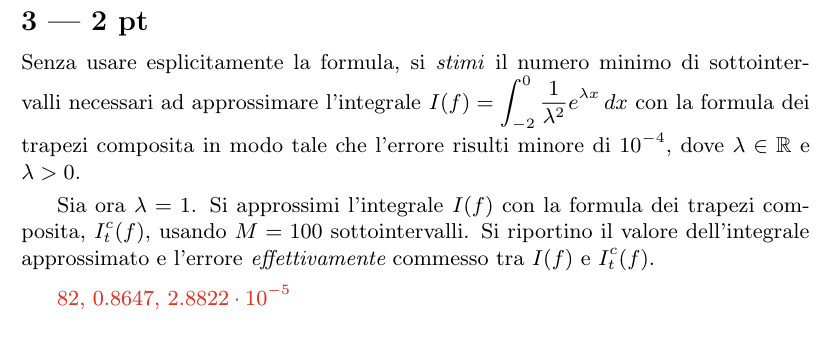

1) $|e_t^c(f)| \le \frac{(b-a)}{12}\,H^2\,\max_{[a,b]}|f''| \qquad H = \frac{b-a}{M}
$

2) calcola f''

3) Trova K = max|f''(x)| su [a, b] (studia f'' nell'intervallo: monotòna → estremi; altrimenti cerca i punti critici).

4) Ricava H

5) Ricava M

### Formule di quadratura di simpson

I = simpcomp(a,b,N,f);

### Formule di quadratura interpolatorie

#### Formule di quadratura di gauss-legendre

Usa la funzione gausscomp_my, implementata per n = 0, 1, 2, 3

## Utili in generale

#### Scelta estremo di integrazione

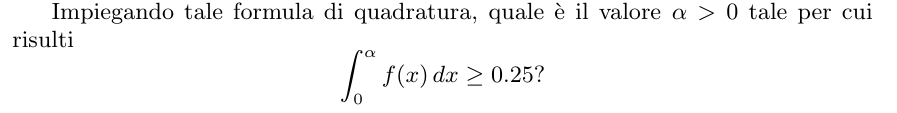

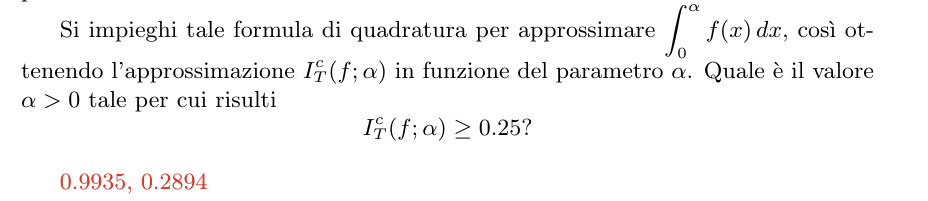

Passaggi:

- Definisci la funzione integranda: f = @(x) ...;

- Definisci g come differenza tra l'approssimazione dell'integrale e il target: g = @(p) METODO(estremo_inf, p, N, f) - target;

- METODO e' la formula di quadratura richiesta (trapcomp, pmedcomp, simpcomp, gausscomp, ...)

- p e' il parametro incognito (puo' essere un estremo, il target, o un altro dato del problema)

- Trova il parametro con metodo numerico: p = fzero(g, guess);

- guess = valore iniziale vicino alla soluzione attesa

- Verifica: disp(p); e ricontrolla METODO(estremo_inf, p, N, f)

- Varianti: se l'incognita non e' un estremo ma sta altrove, basta metterla come argomento di g e lasciarla libera nella chiamata a METODO

%% Risoluzione esercizi: trova parametro tale che quadratura = target
clear; clc;

% --- DATI DA MODIFICARE ---
f = @(x) exp(-x);        % funzione integranda
metodo = @trapcomp;      % formula: @trapcomp, @pmedcomp, @simpcomp, @gausscomp
a = 0;                   % estremo inferiore (fisso)
N = 100;                 % numero sottointervalli
target = 0.25;           % valore da raggiungere
guess = 0.3;             % stima iniziale del parametro incognito

% --- RISOLUZIONE (parametro = estremo superiore b) ---
g = @(p) metodo(a, p, N, f) - target;
p = fzero(g, guess);

% --- OUTPUT ---
fprintf('Parametro trovato: %.6f\n', p);
fprintf('Verifica quadratura: %.6f (target %.6f)\n', metodo(a, p, N, f), target);

% Note rapide per adattarlo:
% - Se l'incognita NON è l'estremo superiore, riscrivi g mettendo p dove serve (es. estremo inferiore, target, o dentro f).
% - Se vuoi passo h fisso invece di N fisso: h = 0.05; e dentro g usa metodo(a, p, round((p-a)/h), f).
% - Controlla l'ordine degli argomenti della tua versione del metodo (a, b, N, f) — alcune funzioni del prof potrebbero avere firma diversa.